format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

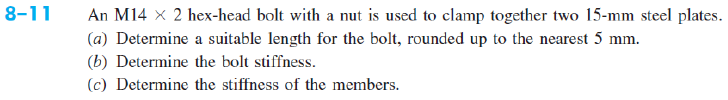

d = 14 * u.mm;
H_b = 9.25 % Højde på bolt hoved (se også table A-31) [mm]

H_b =          9.25


p = 2 * u.mm;
t = 15 * u.mm;              % tykkelse af pladen [mm]
H_m = 12.8 * u.mm;             % Højde på møtrik (se også table A-29) [mm]
R = 0.6;              % Rundingsradius (se også table A-29)[mm]
E = 210 * u. GPa;
l = 2*t

$$l = 30\,\mathrm{mm}$$

alpha = 30 % - trykkegle (mellem 25 og 33 grader, shigley bruger 30 grader) - se også side 17 i bolte 2

alpha =     30


d_w =  21 * u.mm;             % Nøglevidde/Washer face (tabel A-31 se under W)

L_test = t + t + H_m;          % Gevindlængde  [mm]
L_test_ = vpa(L_test, 3)

$$L\_test\_ = 42.8\,\mathrm{mm}$$


L = 45 * u.mm

$$L = 45\,\mathrm{mm}$$


if separateUnits(L) <= 125 && separateUnits(d) <= 48
    L_T = 2*d + 6 * u.mm
elseif 125 < separateUnits(L) && separateUnits(L)<= 200
    L_T = 2 * d + 12
elseif separateUnits(L) > 200
    L_T = 2 * d + 25
else
    disp("Hmmm something is wrong")
end

$$L\_T = 34\,\mathrm{mm}$$


A_d = pi/4 * d^2;   % Skaftareal [mm^2]
A_t = 115 * u.mm^2 %pi/4 * d_t^2; % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t

$$A\_t = 115\,{\mathrm{mm}}^{2}$$

l_d = L - L_T

$$l\_d = 11\,\mathrm{mm}$$

l_t = l - l_d         % Gevindlængde i indgreb  [mm]

$$l\_t = 19\,\mathrm{mm}$$


% For gevindstykket gælder
k_d = vpa(unitConvert((A_d * E) / l_d, u.MN), 5) %ligning 8-16

$$k\_d = 2938.8\,\frac{\mathrm{MN}}{m}$$




%samlede stivhed når to elementer klemme sammen
k_b = vpa(unitConvert((A_d * A_t * E) / (A_d * l_t + A_t * l_d), u.MN), 5)

$$k\_b = 887.29\,\frac{\mathrm{MN}}{m}$$



% Stivhed for matrialet
k_m = (pi * E * d * tand(alpha)) /...
    (2 * log(((l * tand(alpha) + d_w - d) * (d_w + d)) / ...
    ((l * tand(alpha) + d_w + d) * (d_w - d)) ) ); %ligning 8 -21 forudsætter at begge emner er af stål

k_m = vpa(unitConvert(k_m, u.MN), 5)

$$k\_m = 3161.5\,\frac{\mathrm{MN}}{m}$$

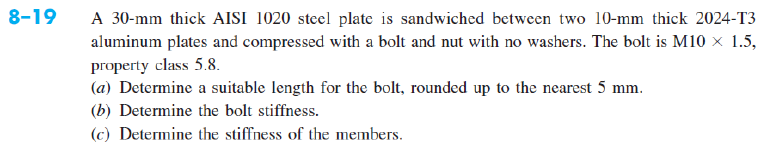

clear
format shortG
u = symunit;

d = 10 * u.mm;             % Nominel diameter (skaft)  [mm]
p = 1.5 * u.mm;
d_w =  16 * u.mm;             % Nøglevidde/Washer face (tabel A-31 se under W)
t_1 = 10 * u.mm;              % tykkelse af pladen [mm]
t_2 = 30 * u.mm;              % tykkelse af pladen [mm]
E_s = 207 * u. GPa;   % for stål 207 * u. GPa E-modul, E = 71 * u.GPa; for Alu se tabel (8-8)
E_a = 71 * u.GPa;

S_ut = 520 * u. MPa; %
S_y = 420 * u. MPa; %S_ut * 0.8
S_p = 380 * u. MPa;

% l =  100;           %Klemme længde (regnes kun til midt i underlagets nedre del) [mm]

% L_T = 130;          % Gevindlængde  [mm] %se også if statment nedenfor



H_b = 6.85 * u.mm;             % Højde på bolt (se også table A-29) [mm]
H_n = 8.4 * u.mm;             % Højde på møtrik (se også A-31 for møtrikker) [mm]
W = 16 * u.mm;             % Nøglevidde eller washer face se table A-29 [mm]

L = t_1*2 + t_2 + H_n          % Boltlængde  [mm]

$$L = \frac{292}{5}\,\mathrm{mm}$$

vpa(L,4)

$$ans = 58.4\,\mathrm{mm}$$

L = 60 * u.mm

$$L = 60\,\mathrm{mm}$$


A_t = 58 * u.mm^2; %pi/4 * d_t^2; % Trækspændingsareal (Se tabel 8-1) eller udregn med d_t
A_d = pi/4 * d^2   % Skaftareal [mm^2]

$$A\_d = 25\,\pi \,{\mathrm{mm}}^{2}$$


alpha = 30; % - trykkegle (mellem 25 og 33 grader, shigley bruger 30 grader) - se også side 17 i bolte 2


%længde af gevind(L_T) følger normalt (8-14)

if separateUnits(L) <= 125 && separateUnits(d) <= 48
    L_T = 2*d + 6 * u.mm
elseif 125 < separateUnits(L) && separateUnits(L) <= 200
    L_T = 2 * d + 12 * u.mm
elseif separateUnits(L) > 200
    L_T = 2 * d + 25 * u.mm
else
    disp("Hmmm something is wrong")
end

$$L\_T = 26\,\mathrm{mm}$$


l = 2*t_1 + t_2

$$l = 50\,\mathrm{mm}$$

l_d = L - L_T         % Skaft længde  [mm]

$$l\_d = 34\,\mathrm{mm}$$

l_t = l - l_d         % Gevindlængde i indgreb  [mm]

$$l\_t = 16\,\mathrm{mm}$$

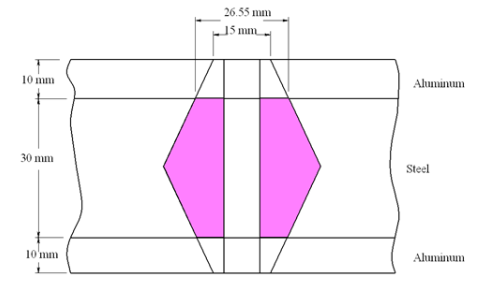

%Stivhed for bolten når stykket uden og med gevind lægges sammen sammen
k_b = (A_d * A_t * E_s) / (A_d * l_t + A_t * l_d)

$$k\_b = \frac{300150\,\pi }{1972\,{\mathrm{mm}}^{3}+400\,\pi \,{\mathrm{mm}}^{3}}\,\mathrm{GPa}\,{\mathrm{mm}}^{4}$$

k_b = vpa(unitConvert((A_d * A_t * E_s) / (A_d * l_t + A_t * l_d), u.MN), 5) % ligning 8-17

$$k\_b = 292.06\,\frac{\mathrm{MN}}{m}$$



% Stivhed for matrialet med forskellige E-moduler
%ligges sammen til sidst.

%for alu
k_ma =  0.5774 * pi * E_a * d /...
    log( ((1.155 * t_1 + d_w - d) * (d_w + d)) /...
    ((1.155 * t_1 + d_w + d) * (d_w - d)) )

$$k\_ma = \frac{204977\,\pi }{500\,\log\left(\frac{1521}{751}\right)}\,\mathrm{GPa}\,\mathrm{mm}$$


k_ma = vpa(unitConvert(k_ma, u.MN), 5)

$$k\_ma = 1825.0\,\frac{\mathrm{MN}}{m}$$


d_w_con = d_w + 2 * tand(alpha) * t_1 %forsatte spændings kegle efter alu

$$d\_w\_con = 16\,\mathrm{mm}+\frac{20\,\sqrt{3}}{3}\,\mathrm{mm}$$


k_ms =  0.5774 * pi * E_s * d /...
    log( ((1.155 * t_2/2 + d_w_con - d) * (d_w_con + d)) /...
    ((1.155 * t_2/2 + d_w_con + d) * (d_w_con - d)) ) % her deles t_2 med 2 da det går over midten af spændings keglen

$$k\_ms = \begin{array}{l} \frac{597609\,\pi }{500\,\log\left(\frac{\left(26\,\mathrm{mm}+\sigma_{1}\right)\,\left(\frac{933}{40}\,\mathrm{mm}+\sigma_{1}\right)}{\left(6\,\mathrm{mm}+\sigma_{1}\right)\,\left(\frac{1733}{40}\,\mathrm{mm}+\sigma_{1}\right)}\right)}\,\mathrm{GPa}\,\mathrm{mm}\\ \mathrm{where}\\ \sigma_{1}=\frac{20\,\sqrt{3}}{3}\,\mathrm{mm} \end{array}$$


k_ms = vpa(unitConvert(k_ms, u.MN), 5)

$$k\_ms = 12215.0\,\frac{\mathrm{MN}}{m}$$



% samlet stivhed her med et bidrag fra hvert matriale før peaket af keglen
% og et bidrag fra hvert matriale efter.
k_mtot = vpa(1/(2/k_ma + 2/k_ms), 5)

$$k\_mtot = 793.88\,\frac{\mathrm{MN}}{m}$$